UBW_st.name='UBW';
UBW_st.lat=35.8258;
UBW_st.lon=-93.203;
UBW_st.alt=722;


UBW_rd=read_betsy('UBW_head',UBW_st.name);

datevec(UBW_rd.Time(1))

ans =         1993           1           2           0           0           0

datevec(UBW_rd.Time(end))

ans =         2009          10           1           0           0           0

prctile(UBW_rd.U_S,[5 50 95])

ans =    40.1368   73.0300   98.7523

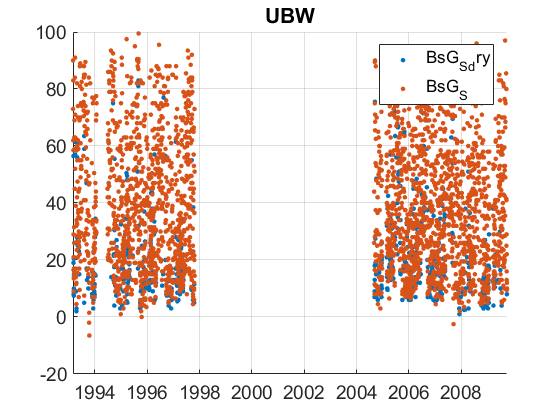

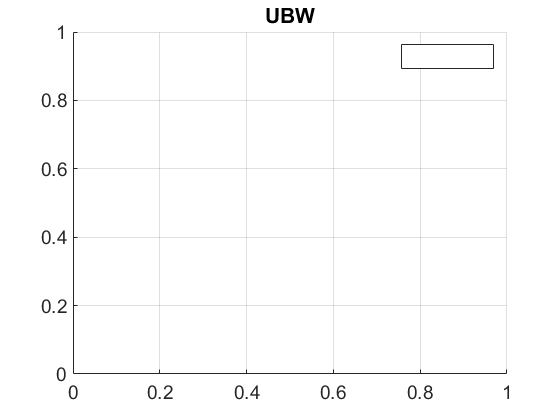

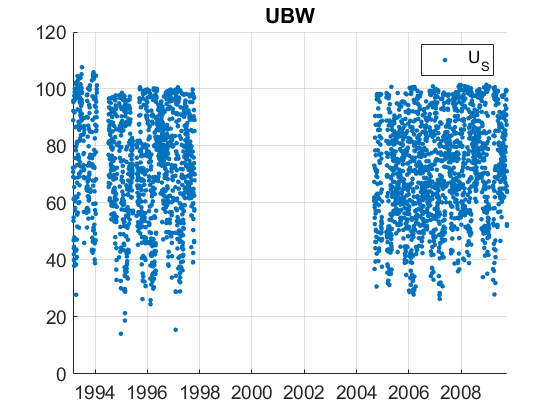

plotFigControl(UBW_rd,UBW_st.name);

% 1 size cut, 
% sc: ok, no clear seasonal cycle, few negatives
%with RH<50 almost no more data


% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE=[467;529;653]*ones(1,4);
% UBW_cal=compute_exp_SSA(UBW_rd,lambdaSC, lambdaAE);
% plotFigControl_cal(UBW_cal,UBW_cal.name);

%Questions:
%problems:
% no data from 1998 to mid 2004


UBW_t=timetable(UBW_rd.Time);
%scat  begin at the beginning of a year: 1993
%end 2008
% neph and abs PM1 to remove
%remove N